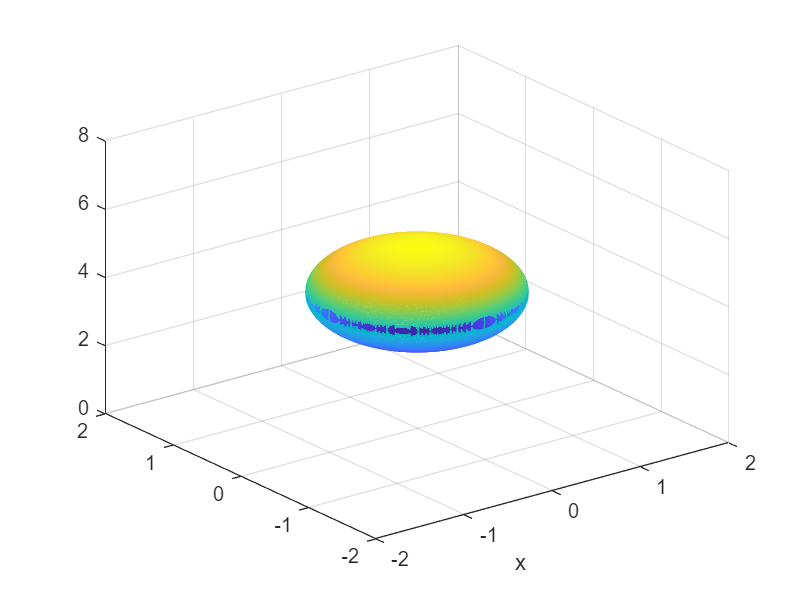

figure
alpha = 1;

[x, y] = meshgrid(-2*alpha:0.01:2*alpha,-2*alpha:0.01:2*alpha);
z1 = 1.33*alpha*(1 - ((x)/(alpha)).^2 - ((y)/(alpha)).^2).^0.5 + 4;
z2 = -1.33*alpha*(1 - ((x)/(alpha)).^2 - ((y)/(alpha)).^2).^0.5 + 4;
z1(imag(z1)~=0) = nan;
mesh(x,y,z1)
xlabel('x')
hold on
z2(imag(z2)~=0) = nan;
mesh(x,y,z2)
xlabel('x')
xlim([-2 2])
ylim([-2 2])
zlim([0 8])
hold off

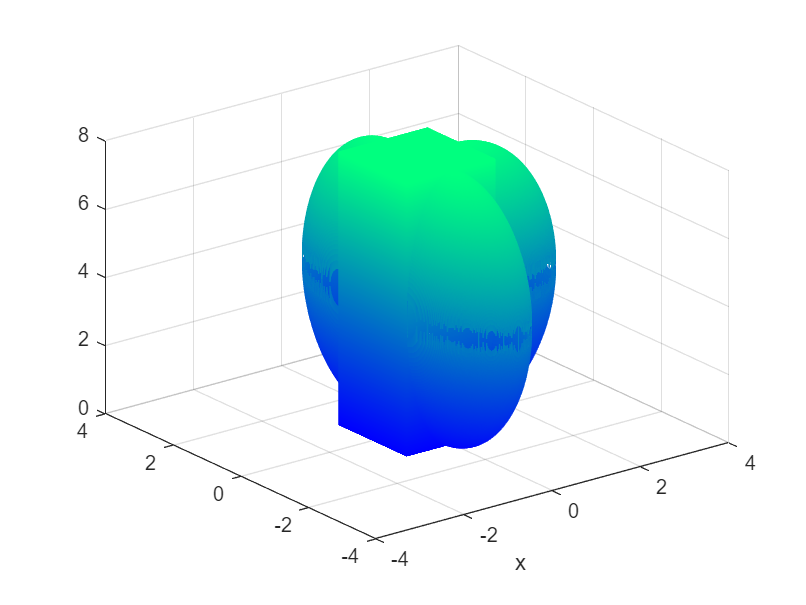

figure
[x, y] = meshgrid(alpha:0.01:2*alpha + alpha,-2*alpha:0.01:2*alpha);
z1 = 4*alpha*(1 - ((x-alpha)/(2*alpha)).^2 - ((y)/(alpha)).^2).^0.5 + 4;
z2 = -4*alpha*(1 - ((x-alpha)/(2*alpha)).^2 - ((y)/(alpha)).^2).^0.5 + 4;
z1(imag(z1)~=0) = nan;
mesh(x,y,z1)
xlabel('x')
hold on
z2(imag(z2)~=0) = nan;
mesh(x,y,z2)
xlabel('x')
xlim([-4 4])
ylim([-4 4])
zlim([0 8])

% fsurf(subs(f, a, 10))
% hold on
% fsurf(subs(g, a, 10))
[x, y] = meshgrid(-2*alpha:0.01:2*alpha,alpha:0.01:2*alpha + 2*alpha);
z1 = 4*alpha*(1 - ((x)/(alpha)).^2 - ((y-alpha)/(2*alpha)).^2).^0.5 + 4;
z2 = -4*alpha*(1 - ((x)/(alpha)).^2 - ((y-alpha)/(2*alpha)).^2).^0.5 + 4;
z1(imag(z1)~=0) = nan;
mesh(x,y,z1)
hold on
z2(imag(z2)~=0) = nan;
mesh(x,y,z2)

[x, y] = meshgrid(-2*alpha:0.01:2*alpha,(-2*alpha:0.01:0) - alpha);
z1 = 4*alpha*(1 - ((x)/(alpha)).^2 - ((y+alpha)/(2*alpha)).^2).^0.5 + 4;
z2 = -4*alpha*(1 - ((x)/(alpha)).^2 - ((y+alpha)/(2*alpha)).^2).^0.5 + 4;
z1(imag(z1)~=0) = nan;
mesh(x,y,z1)
%hold on
z2(imag(z2)~=0) = nan;
mesh(x,y,z2)
xlabel('x')
colormap winter
[c, d] = meshgrid(-1*alpha:0.01:1*alpha,-1*alpha:0.01:1*alpha);
full = ones(size(c*d));
mesh(c,d,4*alpha*full + 4)
hold on
mesh(c,d,-4*alpha*full+4)

mesh(c,alpha*(full),4*d + 4)
mesh(c,-alpha*(full),-4*d + 4)
mesh(alpha*(full),d,4*c + 4)
mesh(-alpha*(full),d,-4*c + 4)